# Week 3 Quiz

Use this file as a starting point for the week 3 quiz. The code to load the trained model and ground truth for the fasteners dataset is provided. You need to write code to evaluate the model and answer the questions in the Coursera quiz. Refer to the EvaluatingObjectDetectionModels.mlx file for assistance.

load fastenerTinyYolo4Detector.mat detector
load fastenerTestGT.mat fastenerTestGT

[imds, blds] = objectDetectorTrainingData(fastenerTestGT);
testData = combine(imds, blds);

## Write code to evaluate the model

To complete this week's quiz you need to do the following steps:

- Run the detector on the test images with a confidence threshold of 0.05

- Evaluate the detection results using an IoU threshold of 0.5 and 0.25

- Compare the AP of all classes at both IoU thresholds

- Compare the mAP at both IoU thresholds

testResults = detect(detector, testData, "Threshold", 0.05);

% Get the list of classes from the detector
classes = detector.ClassNames;
% Evaluate the detection results
[ap, recall, precision] = evaluateDetectionPrecision(testResults, testData, 0.25);
ap

ap =     0.8239
    0.9979
    0.8116
    0.9656


[class, idx] = min(ap)

class = 0.8116

idx = 3


classes(idx)

ans = 1×1 cell array
    {'Screw'}


mean(ap)

ans = 0.8997

% Vector of detection threshold values to test
thresholds = [0.5, 0.25];

classes = detector.ClassNames;

% Create a matrix to store the results
% Each column is the AP returned for the corresponding threshold value
apMatrix = zeros(length(classes), length(thresholds));

% Create a waitbar to monitor progress
f = waitbar(0);

% Loop through the detection thresholds, evaluate results, and save the AP
for ii = 1:length(thresholds)
    results = detect(detector, testData, "Threshold", thresholds(ii));
    apMatrix(:,ii) = evaluateDetectionPrecision(results, testData, 0.5);
    waitbar(ii/length(thresholds), f, "Running detector and evaluating results")
end
close(f)

% Calculate the mAP for each threshold
% The mean function calculates the mean of each column of the matrix
mAPList = mean(apMatrix);

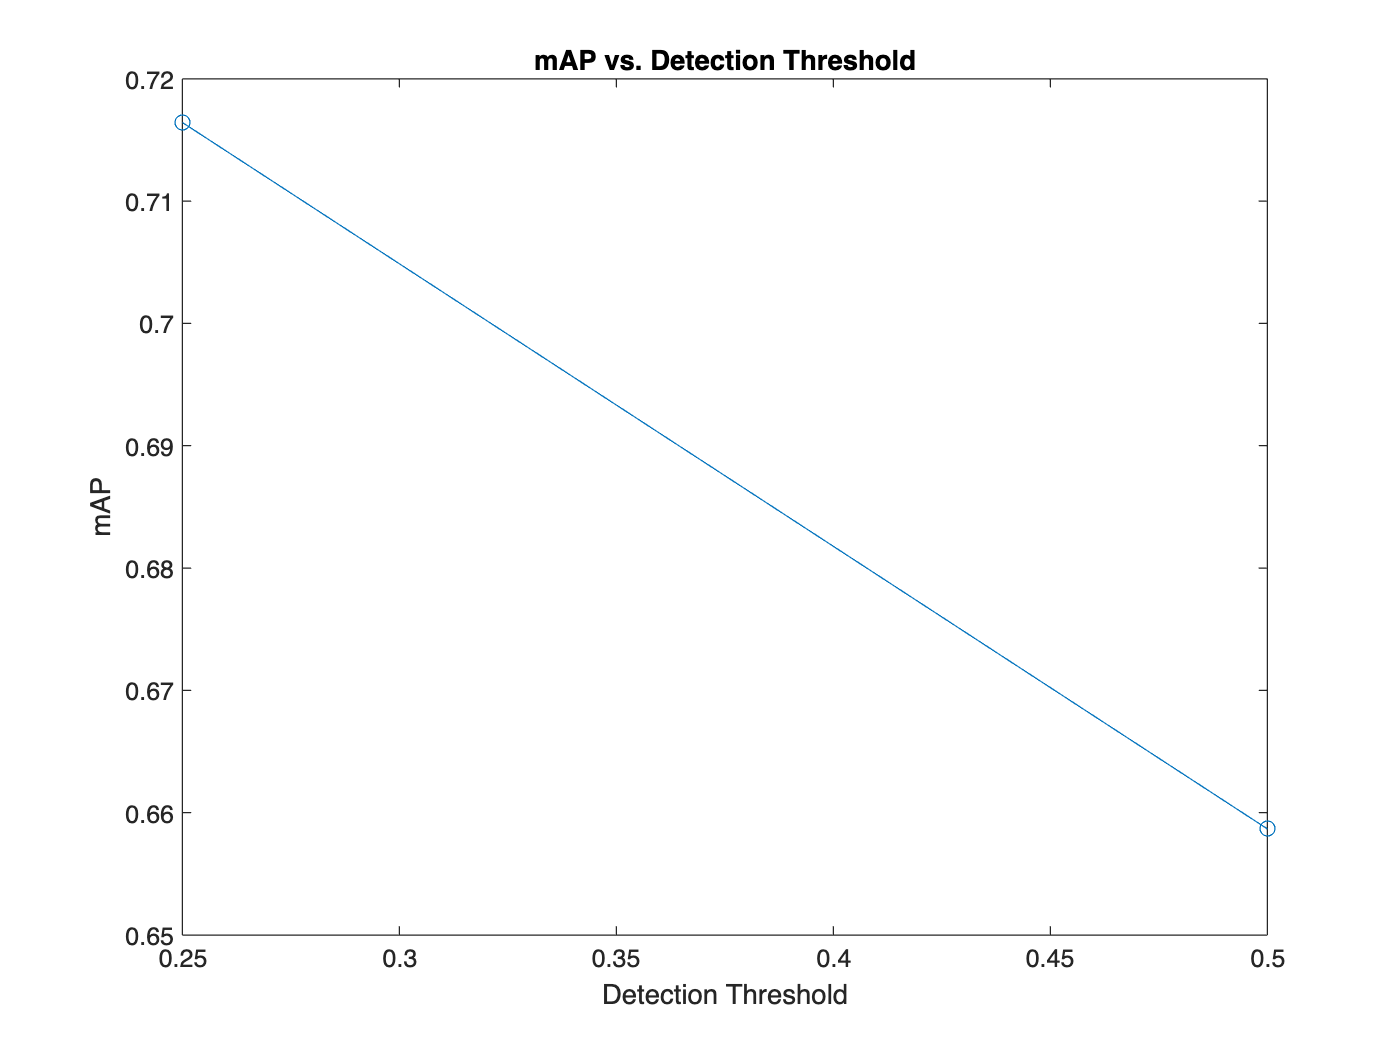

plot(thresholds, mAPList, "-o")
xlabel("Detection Threshold")
ylabel("mAP")
title("mAP vs. Detection Threshold")

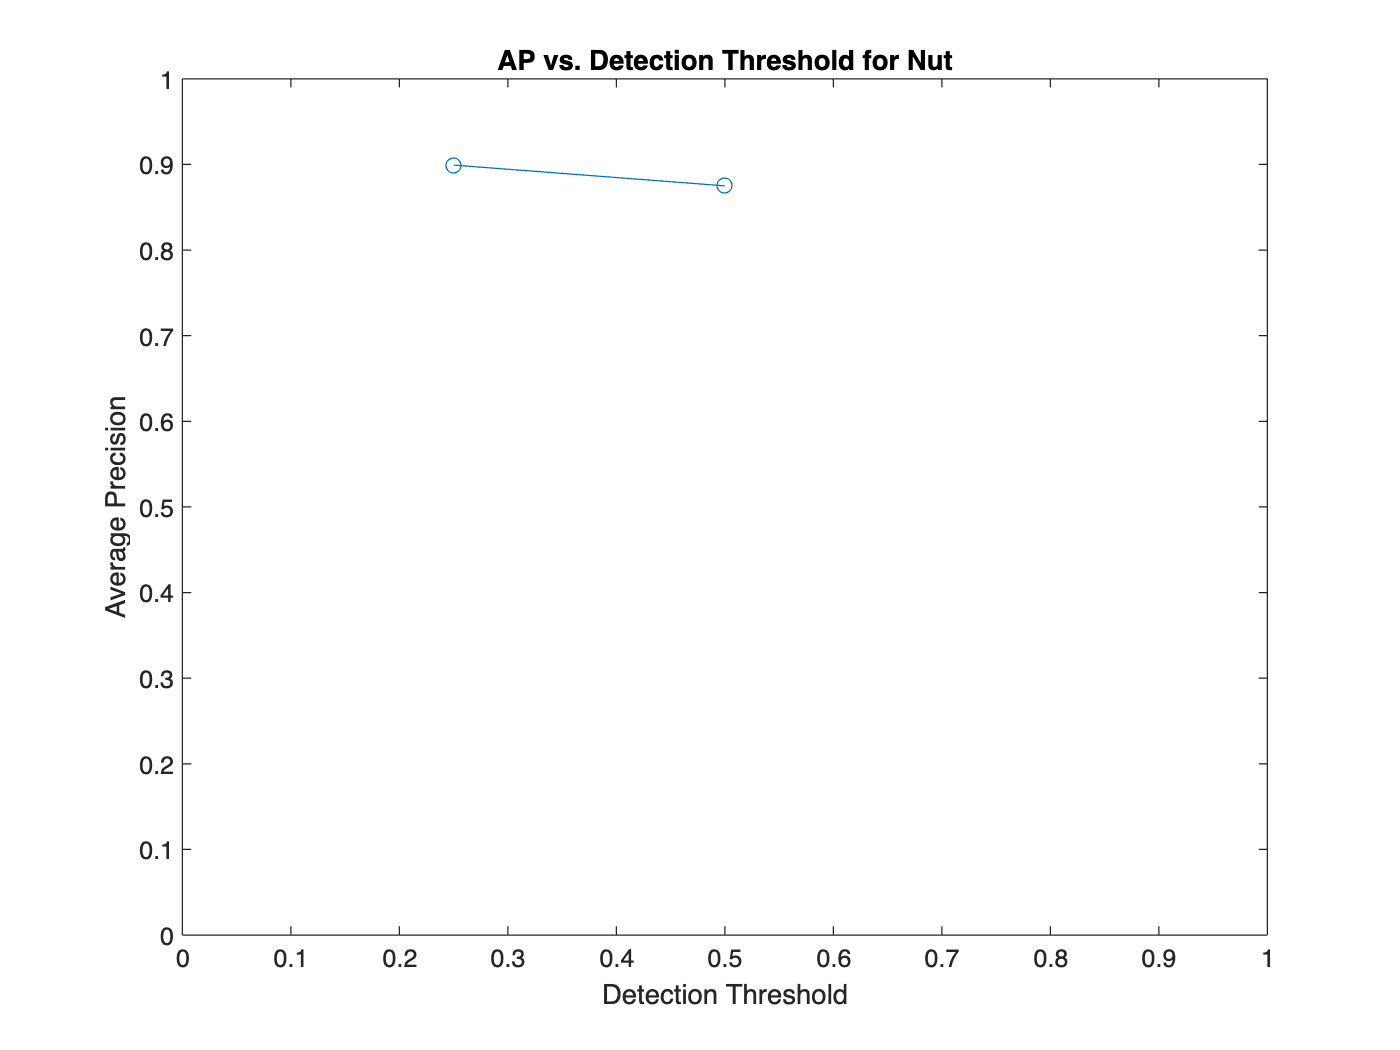

class = 2;
plot(thresholds, apMatrix(class, :), "-o")
title("AP vs. Detection Threshold for " + classes(class))
ylim([0 1])
xlim([0 1])
ylabel("Average Precision")
xlabel("Detection Threshold")

*Copyright 2024 The MathWorks, Inc.*